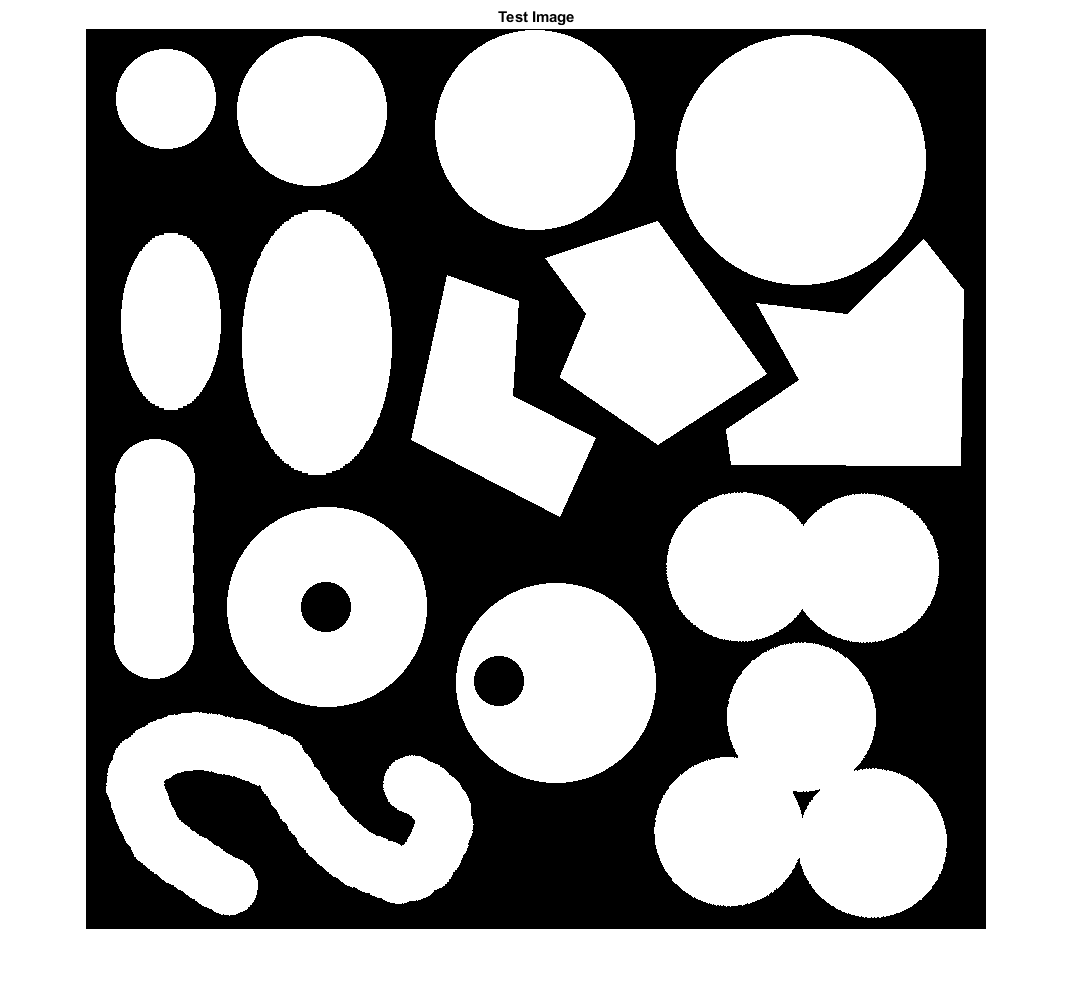

Mask = imread('..\Data\CenterTestImage.bmp');
imshow(Mask)
title('Test Image')

lwd=1;
lvls=6;

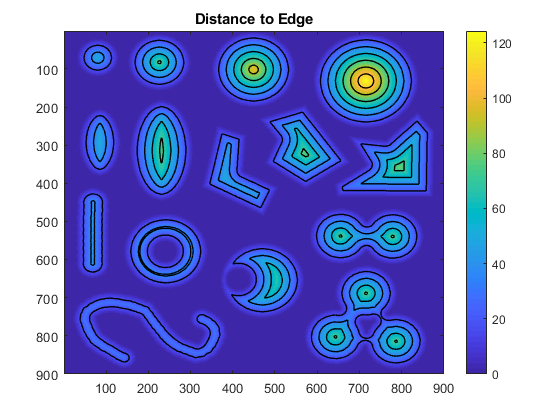

% Distance to Edge
figure
E = bwdist(~Mask);
imagesc(E)
hold on
contour(E,lvls,'-k','LineWidth',lwd)
title('Distance to Edge')
colorbar

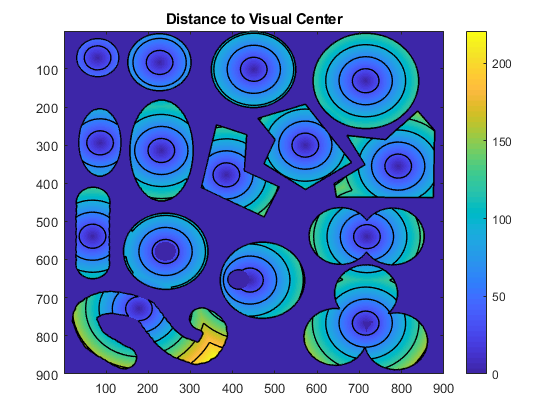

% Distance to Center
figure
[~,~,ctrIm] = BWVisualCenter(Mask);
D = bwdist(ctrIm).*Mask;
imagesc(D)
hold on
contour(D,lvls,'-k','LineWidth',lwd)
title('Distance to Visual Center')
colorbar

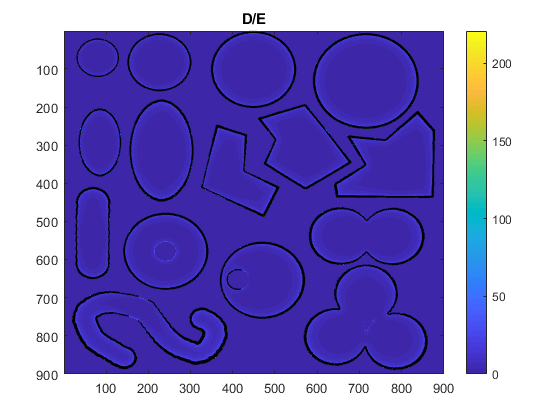

% Distance to Center divided by Distance to Edge
figure
val = D./E;
imagesc(val)
hold on
contour(val,lvls,'-k','LineWidth',lwd)
title('D/E')
colorbar

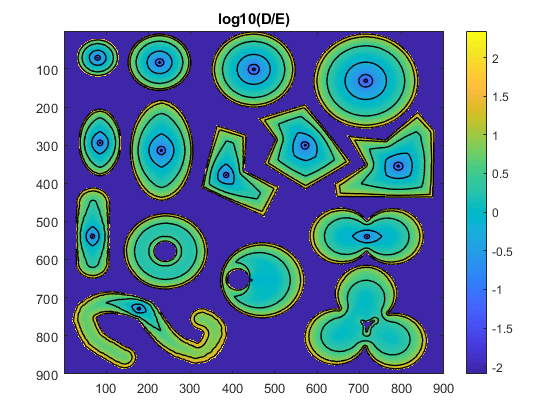

% Log10 of above
figure
val = log10(D./E);
imagesc(val)
hold on
contour(val,lvls,'-k','LineWidth',lwd)
title('log10(D/E)')
colorbar

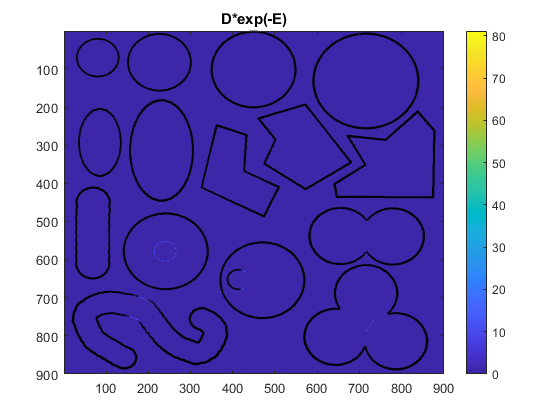

% D*exp(-E)
figure
val = D.*exp(-E);
imagesc(val)
hold on
contour(val,lvls,'-k','LineWidth',lwd)
title('D*exp(-E)')
colorbar

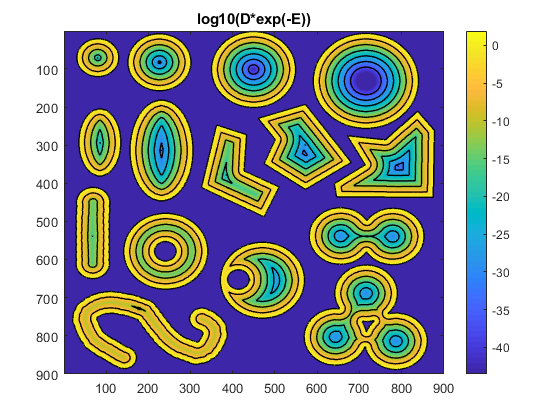

% Log10 of above
figure
val = log10(D.*exp(-E));
imagesc(val)
hold on
contour(val,lvls,'-k','LineWidth',lwd)
title('log10(D*exp(-E))')
colorbar

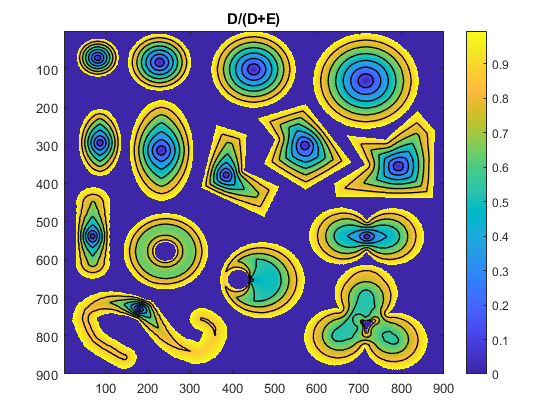

% D/(D+E)
figure
val = D./(D+E);
imagesc(val)
hold on
contour(val,lvls,'-k','LineWidth',lwd)
title('D/(D+E)')
colorbar

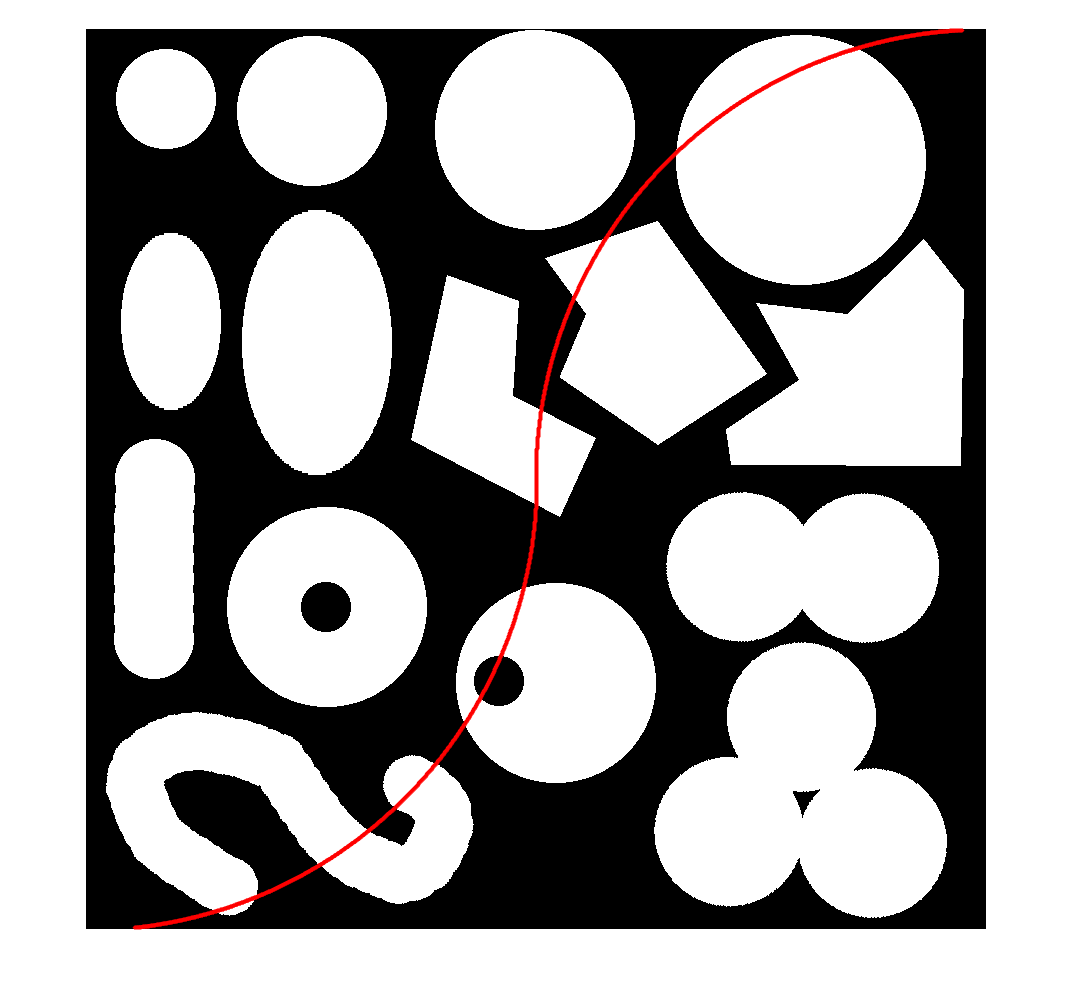

% What about a metric based upon the LPR?
Edge = imread('..\Data\CenterTestImage_Edge.bmp');
[EdgePts,EdgeLine]=Mask2EdgePts(Edge);
figure
imshow(Mask)
hold on
plot(EdgePts(:,1),EdgePts(:,2),'-r','LineWidth',3);

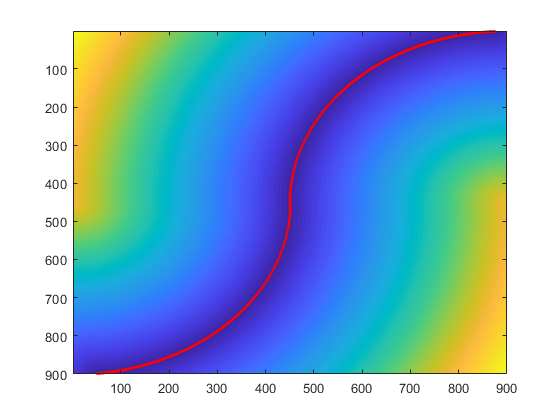

dEdge = bwdist(EdgeLine);
figure
imagesc(dEdge)
hold on
plot(EdgePts(:,1),EdgePts(:,2),'-r','LineWidth',2);

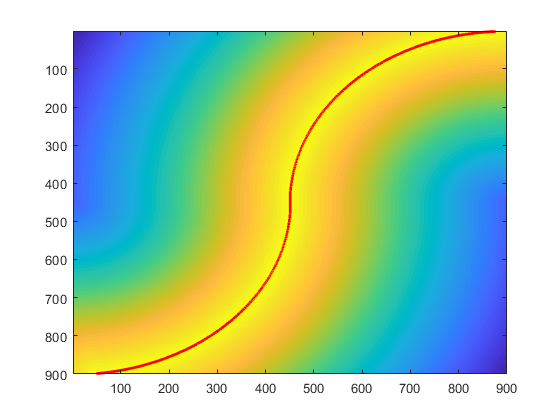


dEdgeI = bwdistInv(EdgeLine);
figure
imagesc(dEdgeI)
hold on
plot(EdgePts(:,1),EdgePts(:,2),'-r','LineWidth',2);

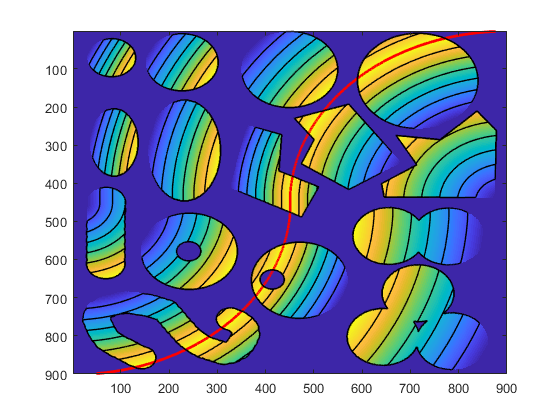

[NormImage] = NormByBWComp(Mask,dEdgeI);
figure
imagesc(NormImage)
hold on
plot(EdgePts(:,1),EdgePts(:,2),'-r','LineWidth',2);
contour(NormImage,lvls,'-k','LineWidth',lwd)

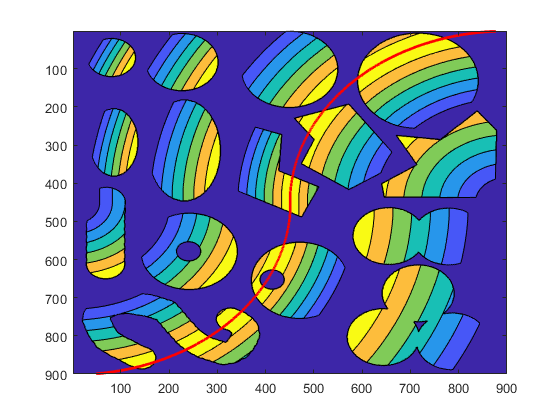


figure
contourf(NormImage,lvls)
hold on
plot(EdgePts(:,1),EdgePts(:,2),'-r','LineWidth',2);
axis ij

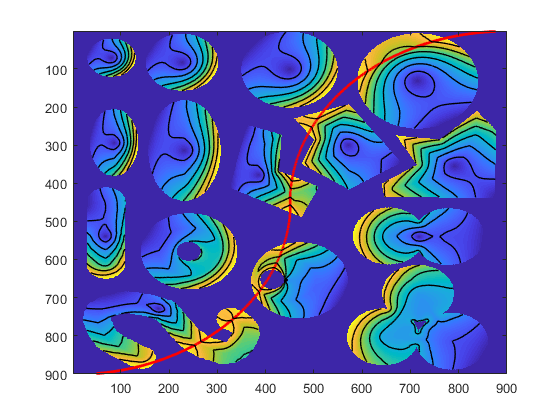

% what about a combo of the two?
figure 
imagesc(NormImage.*val)
hold on
plot(EdgePts(:,1),EdgePts(:,2),'-r','LineWidth',2);
contour(NormImage.*val,lvls,'-k','LineWidth',lwd)

% What if a different type of influence map is used. 
IMap = InfluenceMap(EdgeLine,'Type','Reciprocal');

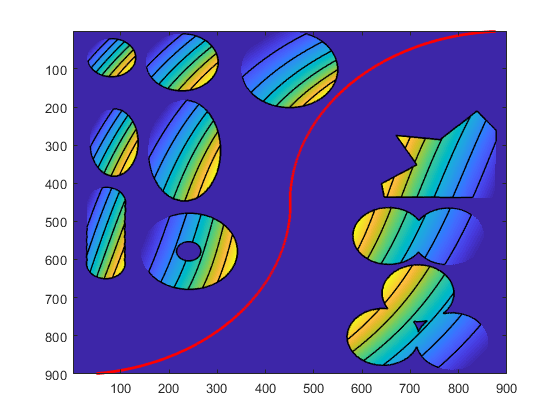

[NormImage] = NormByBWComp(Mask,IMap);
figure
imagesc(NormImage)
hold on
plot(EdgePts(:,1),EdgePts(:,2),'-r','LineWidth',2);
contour(NormImage,lvls,'-k','LineWidth',lwd)

% What if a different type of influence map is used. 
IMap = InfluenceMap(EdgeLine,'Type','Exponential');

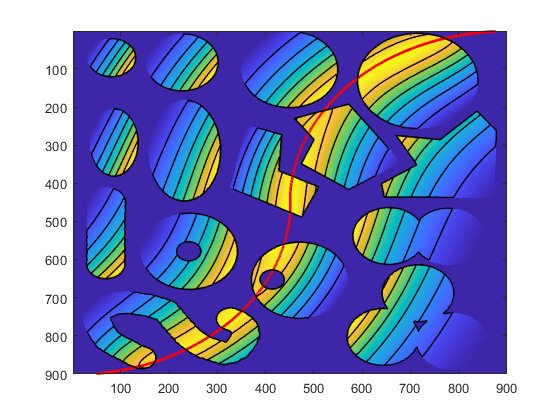

[NormImage] = NormByBWComp(Mask,IMap);
figure
imagesc(NormImage)
hold on
plot(EdgePts(:,1),EdgePts(:,2),'-r','LineWidth',2);
contour(NormImage,lvls,'-k','LineWidth',lwd)

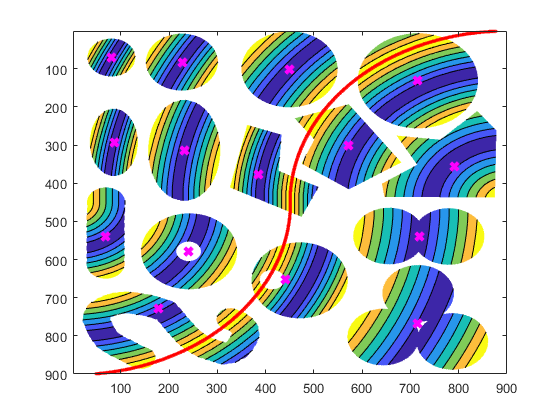

% One problem is that we wont necessarily know where the LPR is going to
% be. Because of this we need to treat really low values and really high
% values as "polar" and middling values as "nonpolar". To fix this issue,
% first normalize on a cell by cell basis between 0 and 1. NormImage has
% alreadly done this. Then invert values less than 0.5. This is relatively
% easy to achieve. 
figure
% Next find values less than 0.5 and "invert" them by subtracting them from 1
[NormImage] = NormByBWComp(Mask,dEdgeI);
pNormImage = 2*abs(NormImage-0.5).*Mask;
pNormImage(~Mask)=NaN;
contourf(pNormImage,lvls)
hold on
plot(EdgePts(:,1),EdgePts(:,2),'.r')
axis ij

% What about the visual center of the cell
[centPts,~,ctrIm] = BWVisualCenter(Mask);
plot(centPts(:,1),centPts(:,2),'xm','MarkerSize',8,'LineWidth',3)

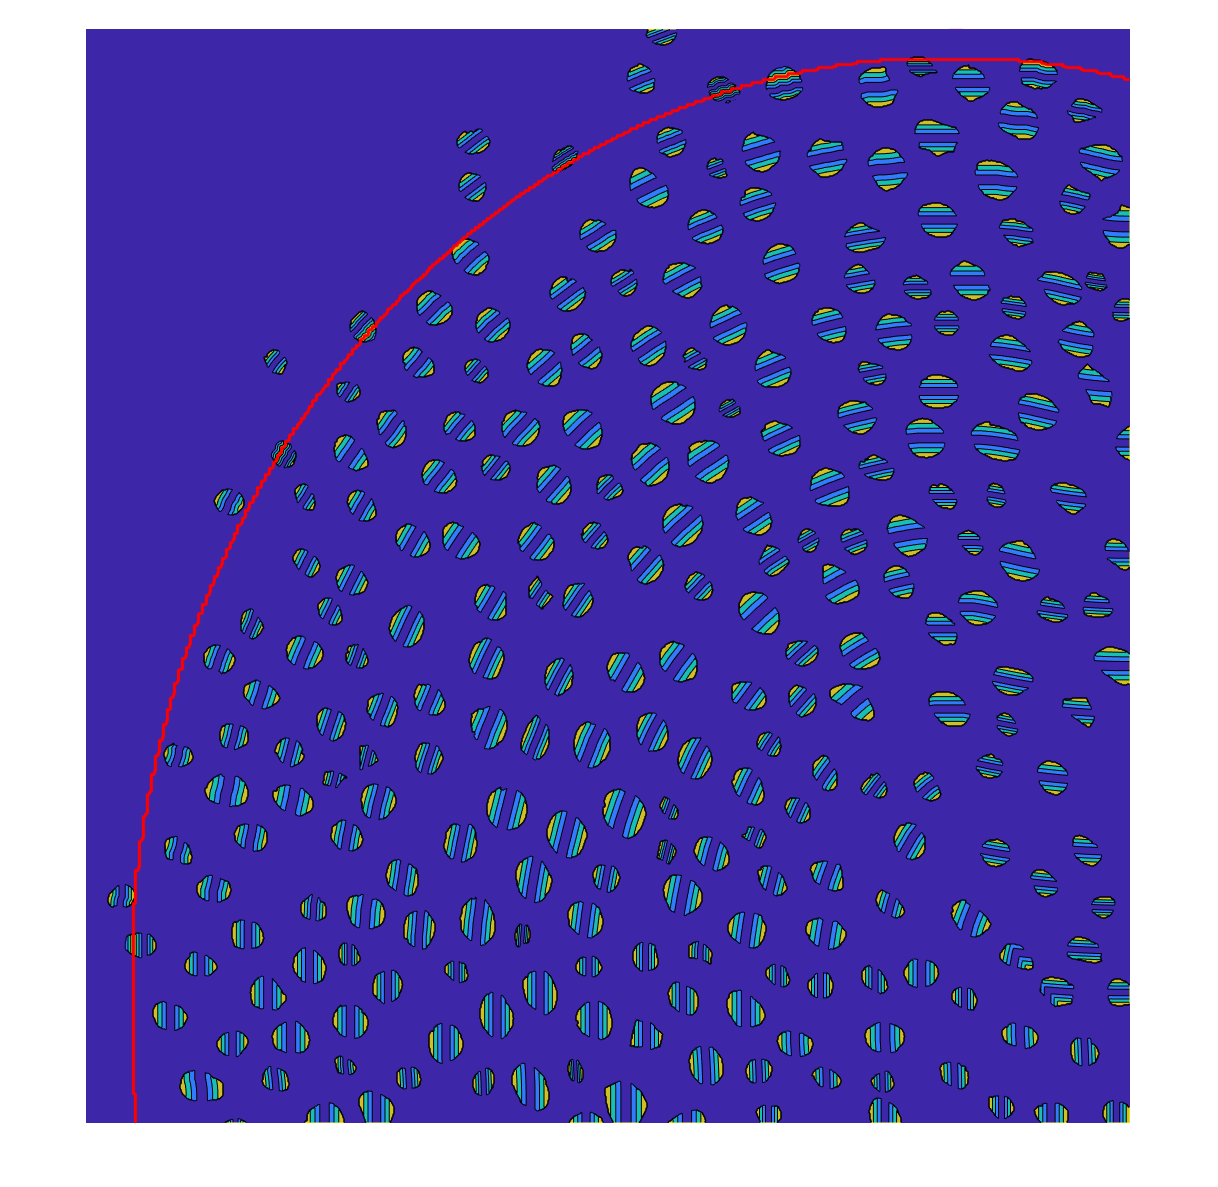

% lets try this on some real data
haircells = ~imread('..\Data\P0\P0_HairCells.bmp');
ubbound = ~imread('..\Data\P0\P0_UtricularBoundary.bmp');

[EdgePts,EdgeLine]=Mask2EdgePts(ubbound);

imshow(haircells)
hold on
plot(EdgePts(:,1),EdgePts(:,2),'.r')


IMap = InfluenceMap(EdgeLine);
[NormImage]= NormByBWComp(haircells,IMap);
pNormImage = 2*abs(NormImage-0.5).*haircells;
contourf(pNormImage,3)
colormap parula
hold on
plot(EdgePts(:,1),EdgePts(:,2),'.r')
axis ij

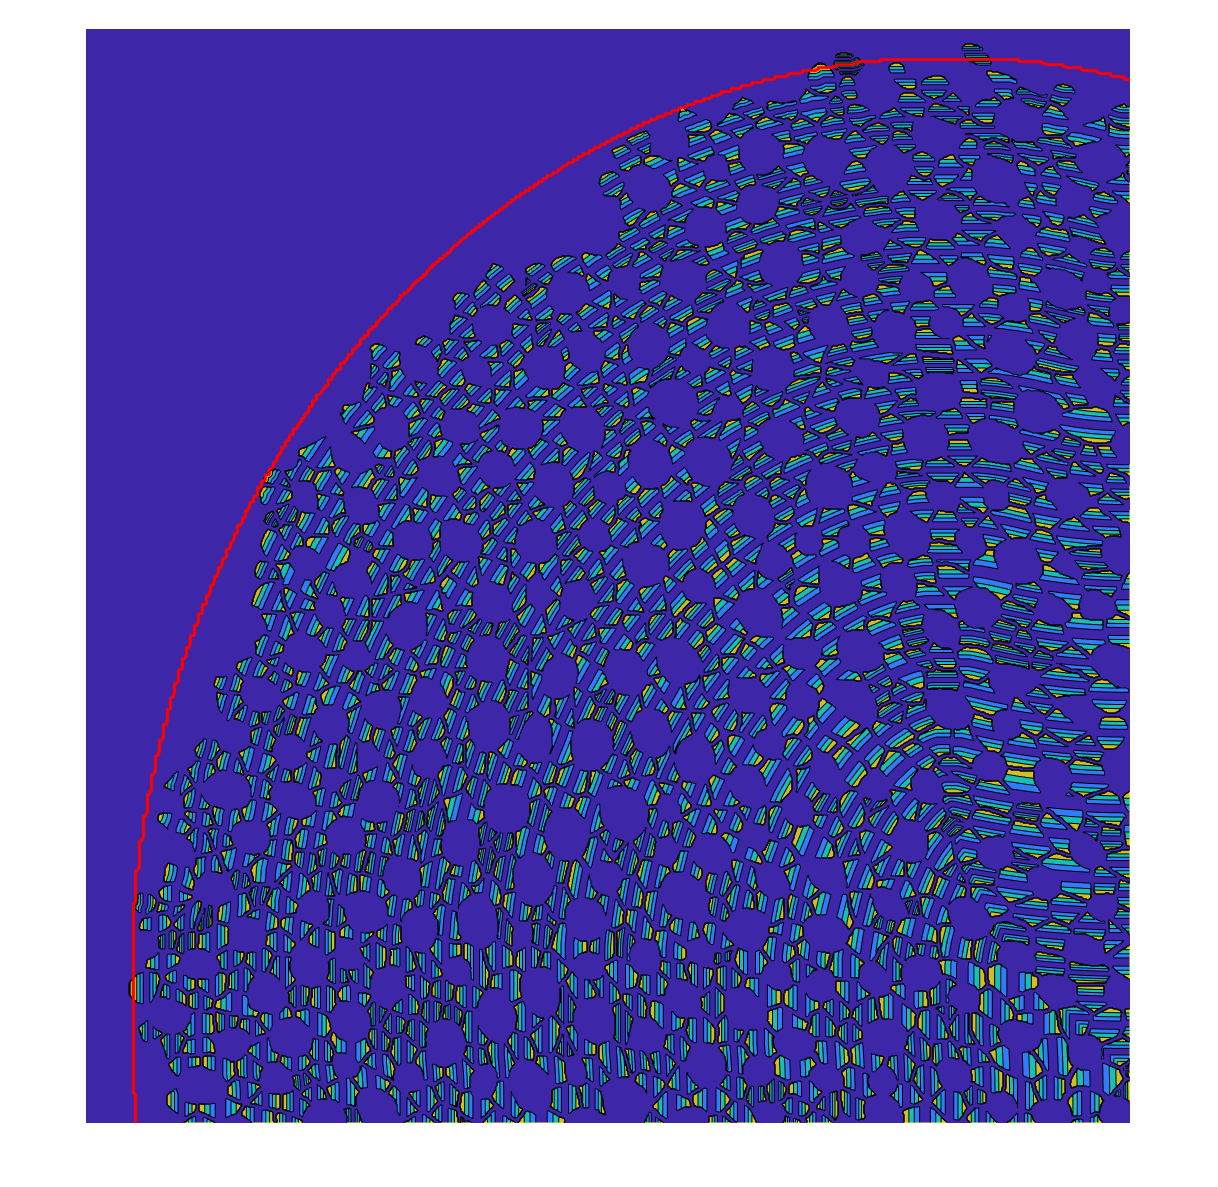

% lets try this on some real data
supportcells = ~imread('..\Data\P0\P0_SupportCells.bmp');
ubbound = ~imread('..\Data\P0\P0_UtricularBoundary.bmp');

[EdgePts,EdgeLine]=Mask2EdgePts(ubbound);

figure
imshow(supportcells)
hold on
plot(EdgePts(:,1),EdgePts(:,2),'.r')


IMap = InfluenceMap(EdgeLine);
[NormImage]= NormByBWComp(supportcells,IMap);
pNormImage = 2*abs(NormImage-0.5).*supportcells;
contourf(pNormImage,3)
colormap parula
hold on
plot(EdgePts(:,1),EdgePts(:,2),'.r')
axis ij

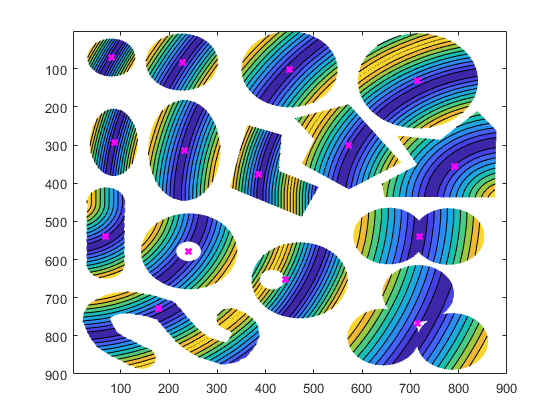

% Test PolarityByFeature
pmap = PolarityByFeature(Mask,Edge);
figure
contourf(pmap)
caxis([0 1])
axis ij
[centPts,~,ctrIm] = BWVisualCenter(Mask);
hold on
plot(centPts(:,1),centPts(:,2),'mx','LineWidth',2)

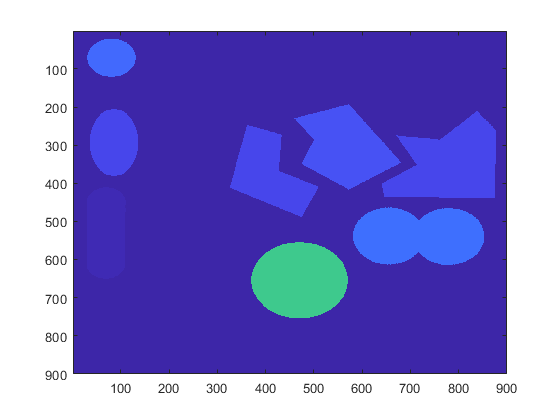


ctrPols = pmap(ctrIm);
ctrPols = [NaN; ctrPols];
maskL = bwlabel(imfill(Mask,'holes'))+1;
ctrInd = maskL(ctrIm);
PolsROrd = [NaN; ctrPols(ctrInd)];
ctrPolMap = PolsROrd(maskL);

figure
imagesc(ctrPolMap)
caxis([0 1])


% force values to adjust to this